# Parking car simulation

clear all;
clc;

addpath(genpath("./utils/"), genpath("./global_planner/"));
load("grid_map_parking.mat");
% map setting
map_size = size(grid_map);
G = 1; 

start = [3, 2];
goal = [17, 18];
goal2 = [4, 27];

planner_name = "a_star";
planner = str2func(planner_name);


## Plan first route

tic
[path, flag, cost, expand] = planner(grid_map, start, goal);
time1 = toc

time1 = 0.0832

disp(path)

    17    18
    16    18
    15    19
    15    20
    15    21
    15    22
    15    23
    14    24
    13    25
    12    26
    11    27
    10    27
     9    27
     8    26
     8    25
     8    24
     8    23
     8    22
     8    21
     8    20
     8    19
     7    18
     6    17
     5    16
     4    15
     3    14
     3    13
     3    12
     3    11
     3    10
     3     9
     3     8
     3     7
     3     6
     3     5
     3     4
     3     3
     3     2



## Plan second route

newstart = [path(end - 14, 1), path(end - 14, 2)];
tic
[path2, flag2, cost2, expand2] = planner(grid_map, newstart, goal2);
time2 = toc

time2 = 0.0107

## Visualize route

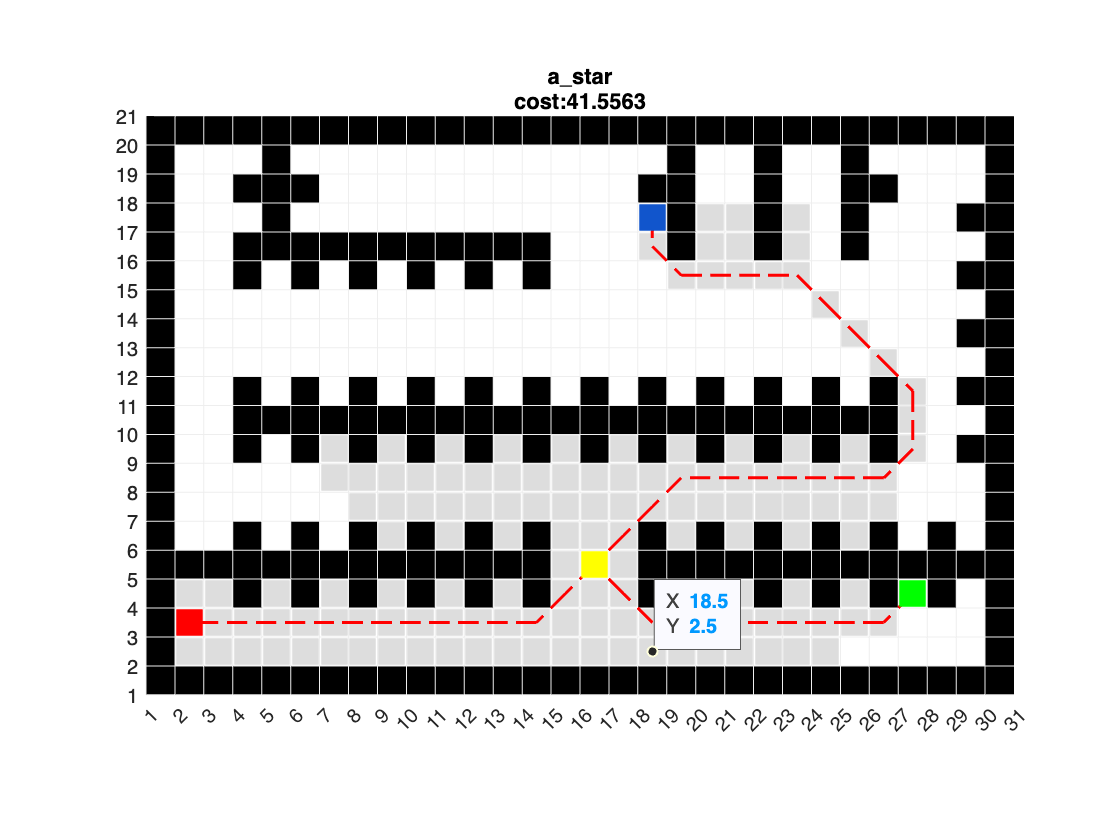

clf; hold on
% plot grid map
plot_grid(grid_map);

% plot expand zone
plot_expand(expand, map_size, G, planner_name);
plot_expand(expand2, map_size, G, planner_name);
% plot path
plot_path(path, G);
plot_path(path2, G)
% plot start and goal
plot_square(start, map_size, G, "#f00");
plot_square(goal, map_size, G, "#15c");
plot_square(goal2, map_size, G, "green");
plot_square(newstart, map_size, G, "yellow");

% title
title([planner_name, "cost:" + num2str(cost)], 'Interpreter','none');

hold off

ax = gca;
chart = ax.Children(91);
datatip(chart,19,1);